clear 
close all
scene = uavScenario(UpdateRate=2);
Map = 4;
addMesh(scene,"polygon",{[11 9;13 9;13 10;11 10],[0 5]},0.651*ones(1,3))
scene

scene =   uavScenario with properties:

           UpdateRate: 2
             StopTime: Inf
    HistoryBufferSize: 100
    ReferenceLocation: [0 0 0]
         MaxNumFrames: 10
          CurrentTime: 0
            IsRunning: 0
        TransformTree: [1×1 transformTree]
       InertialFrames: ["ENU"    "NED"]
               Meshes: {[1×1 extendedObjectMesh]}
            Platforms: [0×0 uavPlatform]


scene.Meshes{1,1}

ans =   extendedObjectMesh with properties:

    Vertices: [8×3 double]
       Faces: [12×3 double]


scene.Meshes{1,1}.Vertices

ans =     11     9     0
    11    10     0
    13    10     0
    13     9     0
    11     9     5
    11    10     5
    13    10     5
    13     9     5


scene.Meshes{1,1}.Faces

ans =      1     5     2
     2     6     3
     3     7     4
     4     8     1
     2     5     6
     3     6     7
     4     7     8
     1     8     5
     2     4     1
     2     3     4


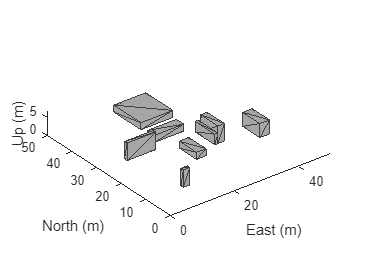


%MAP3
%----------------------------------------------------------------
if Map == 3
    addMesh(scene,"polygon",{[11 9;13 9;13 10;11 10],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[31 4;33 4;33 15;31 15],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[19 24;31 24;31 25;19 25],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[43 20;44 20;44 26;43 26],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[31 27;46 27;46 40;31 40],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[26 36;29 36;29 37;26 37],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[5 28;16 28;16 38;5 38],[0 5]},0.651*ones(1,3))
    %addMesh(scene,"polygon",{[0 0;50 0;50 50;0 50],[0 2]},0.651*ones(1,3))
    uavPose = [6 12 -3 pi/2 0 0]';
    goalPose = [35 27 -3]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=[6 12 -3; 35 27 -3]);

%MAP2
%------------------------------------------------------------------------
elseif Map == 2
    addMesh(scene,"polygon",{[8 10;20 10;20 25;8 25],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[26 18;29 18;29 31;26 31],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[33 21;37 21;37 34;33 34],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[39 13;42 13;42 26;39 26],[0 4]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[1 27;16 27;16 40;1 40],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[14 42;25 42;25 44;14 44],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[27 40;39 40;39 50;27 50],[0 5]},0.651*ones(1,3))
    uavPose = [10 35 -5 pi/2 0 0]';
    goalPose = [45 5 -2]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=[10 35 -5; 45 5 -2]);

%MAP1
%--------------------------------------------------------------------------

elseif Map == 1
    addMesh(scene,"polygon",{[12 3;19 3;19 18;12 18],[0 4]},0.651*ones(1,3))  
    addMesh(scene,"polygon",{[30 10;42 10;42 15;30 15],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[38 17;50 17;50 24;38 24],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[5 23;7 23;7 24;5 24],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[16 27;24 27;24 36;16 36],[0 2]},0.651*ones(1,3))

    addMesh(scene,"polygon",{[31 31;46 31;46 39;31 39],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[5 37;18 37;18 42;5 42],[0 5]},0.651*ones(1,3))
    uavPose = [27 47 -2 pi/2 0 0]';
    goalPose = [5 10 -2]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=[27 47 -2; 5 10 -2]);

else
%MAP 4
%-------------------------------------------------------------------------
    addMesh(scene,"polygon",{[8 28;17 28;17 29;8 29],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[22 18;25 18;25 25;22 25],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[30 21;31 21;31 29;30 29],[0 3]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[31 21;33 21;33 28;31 28],[0 5]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[19 31;28 31;28 34;19 34],[0 2]},0.651*ones(1,3))

    addMesh(scene,"polygon",{[20 38;30 38;30 49;20 49],[0 2]},0.651*ones(1,3))
    addMesh(scene,"polygon",{[41 17;44 17;44 24;41 24],[0 4]},0.651*ones(1,3))
    uavPose = [35 3 -3 pi/2 0 0]';
    goalPose = [10 35 -5]';
    wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=[35 3 -3; 10 35 -5]);
end

show3D(scene);
xlim([0 50])
ylim([0 50])
zlim([0 7])

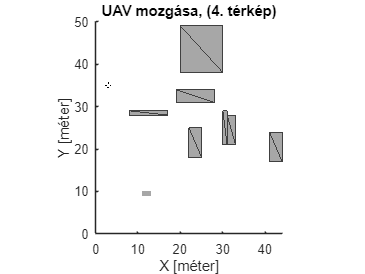

model = multirotor;






plat = uavPlatform("UAV",scene, ...
                   ReferenceFrame="NED", ...
                   InitialPosition=uavPose(1:3)', ...
                   InitialOrientation=eul2quat(uavPose(4:6)'));


updateMesh(plat,"quadrotor",{1.5},[0 0 0],eul2tform([0 0 pi]))
lidarmodel = uavLidarPointCloudGenerator(AzimuthResolution=0.3324099, ...
                                         ElevationLimits=[-10 30], ...
                                         AzimuthLimits=[-60 60], ...
                                         ElevationResolution=0.5, ...
                                         MaxRange=10, ...
                                         UpdateRate=2, ...
                                         HasOrganizedOutput=true);

lidar = uavSensor("Lidar",plat,lidarmodel, ...
                  MountingLocation=[0 0 -0.4], ...
                  MountingAngles=[0 0 180]);

figure(1)
[ax,plotFrames] = show3D(scene);
ax.Children(end).LineStyle = "none";

title("UAV mozgása, (" + Map +". térkép)")
xlim([0 50])
ylim([0 50])
zlim([0 7])
view(ax,2)
xlabel(ax, "X [méter]")
ylabel(ax, "Y [méter]")
zlabel(ax, "Z [méter]")
axis(ax,"equal")
hold(ax,"on")



vfh3D = controllerVFH3D(HistogramResolution=5, ...
                        MaxAge=0, ...
                        HorizontalSensorFOV=lidarmodel.AzimuthLimits, ...
                        VerticalSensorFOV=lidarmodel.ElevationLimits, ...
                        SensorLocation=lidar.MountingLocation, ...
                        SensorOrientation=lidar.MountingAngles([3 2 1]));

% Specify lookahead distance for the desired point along obstacle-free
% direction, and for the waypoint follower. 
lookaheadOA = 2;
lookaheadWF = 6;

% Set up UAV initial state. The UAV state space is position, linear velocity,
% attitude Euler angles, angular velocity, thrust and integral error.
uavPosition = uavPose(1:3);
uavOrientation = eul2quat(uavPose(4:6)')';
intErr = [0;0;0];
initialState = [uavPosition(1); uavPosition(2); uavPosition(3); ...
                0; 0; 0; uavPose(4); 0; 0; 0; 0; 0; 0; intErr];

% Set the PID controller parameters.
kp = 15;
kd = 12;
ki = 0.005;
kyaw = 10;

% Set up simulation start time and integration interval.
tStart = 0;
tStep = 0.1;

% Solution time points.
hStep = tStep/10;

% Number of iterations.
numIter = 400;

% Store time and states.
tTotal = zeros(numIter*(tStep/hStep+1),1);

% Number of states is equal to the number of model states plus
% integral error.
numStates = numel(model.state)+3;
states = zeros(numIter*(tStep/hStep+1),numStates);

vfh3D.DistanceLimits = [0.1 2];

vfh3D.TargetDirectionWeight = 5;
vfh3D.PreviousDirectionWeight = 2;
vfh3D.CurrentDirectionWeight = 2;

vfh3D.VehicleRadius = 0.5;     
vfh3D.SafetyDistance = 0.5;  


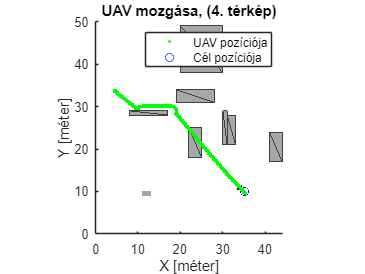

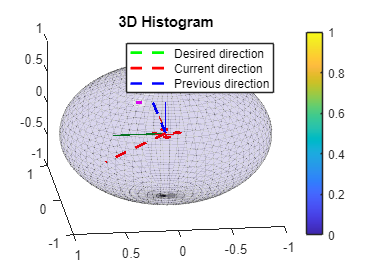

Reached = logical
   1


setup(scene)
Reached = false;
idx = 1;
while ~Reached
% Simulate 
%for idx = 1:numIter
    
    [isupdated,lidarSampleTime,pt] = read(lidar);
    xLidar = reshape(pt.Location(:,:,1),[],1);
    yLidar = reshape(pt.Location(:,:,2),[],1);
    zLidar = reshape(pt.Location(:,:,3),[],1);

    sensorPoints = [xLidar yLidar zLidar];
  
    [targetPosition,~,desYaw] = wf(uavPose(1:4),lookaheadWF);

    [desiredDirection,desiredYaw,status] = vfh3D(uavPosition,uavOrientation, ...
                                                 sensorPoints,goalPose);

    % Visualize the histogram.
    figure(2)
    show(vfh3D);


    % Select desired position along the obtacle-free direction.
    desiredPosition = uavPosition + lookaheadOA*desiredDirection;
    desUAVPoz = uavPosition;
    desUAVPoz(1) = uavPosition(1) + 0.2*desiredDirection(1);
    desUAVPoz(2) = uavPosition(2) + 0.2*desiredDirection(2);
    desUAVPoz(3) = uavPosition(3) - 0.2*desiredDirection(3);
    [t,y] = ode23(@(t,x)exampleHelperDerivative(t,x,model,desiredPosition,desiredYaw,kp,kd,ki,kyaw), ...
                  tStart:hStep:tStart + tStep,initialState);

    % Store data.
    tTotal((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1)) = t;
    states((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1),:) = y;

    % Update states.
    uavPosition = y(end,1:3)';
    %uavPosition = desUAVPoz;
    uavOrientEul = y(end,7:9)';
    uavOrientation = eul2quat(uavOrientEul')';
    tStart = t(end);
    initialState = y(end,:);
  
    % Plot the path.
    desPosition = plot3(desiredPosition(2),desiredPosition(1),-desiredPosition(3),".g",Parent=ax);
    %tgtPosition = plot3(targetPosition(2),targetPosition(1),-targetPosition(3),".r",Parent=ax);
    goalPosition = plot3(wf.Waypoints(end,2),wf.Waypoints(end,1),-wf.Waypoints(end,3),"ob",Parent=ax);
    legend(ax,[desPosition goalPosition],["UAV pozíciója","Cél pozíciója"])
   
    if isupdated
        % Use fast update to move platform visualization frames.
        show3D(scene,Parent=ax,Time=lidarSampleTime,FastUpdate=true);
        % Move the platform.
        move(plat,[uavPosition' y(end,4:6) zeros(1,3) eul2quat(uavOrientEul') zeros(1,3)]);
        drawnow limitrate
    end

    % Advance scene simulation time.
    advance(scene);

    % Update all sensors in the scene.
    updateSensors(scene)

    uavPose = [uavPosition; quat2eul(uavOrientation',"ZYX")'];
    ReachedCoordinates = abs(uavPose(1:3)-goalPose);
    if ReachedCoordinates(1) < 1 && ReachedCoordinates(2) < 1 && ReachedCoordinates(3) < 1
        Reached = true
    end
    idx = idx+1;
end

figure(3)
idx

idx = 181

(idx-1)*(tStep/hStep+1)

ans = 1980

hStep

hStep = 0.0100

states((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1),:)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


states

states =    35.0000    3.0000   -3.0000         0         0         0    1.5708         0         0         0         0         0         0         0         0         0
   35.0000    3.0000   -3.0001   -0.0025    0.0024   -0.0317    1.6381   -0.0518    0.0498    8.4059   -8.1661    7.1537    1.3087   -0.0135    0.0147   -0.0009
   34.9999    3.0001   -3.0006   -0.0157    0.0135   -0.0609    1.7022   -0.1460    0.1380    9.8123   -8.6740    7.2920    1.2630   -0.0270    0.0295   -0.0017
   34.9996    3.0003   -3.0013   -0.0416    0.0329   -0.0831    1.7603   -0.2350    0.2211    8.8224   -6.6274    6.9966    1.2308   -0.0405    0.0442   -0.0026
   34.9990    3.0008   -3.0023   -0.0784    0.0571   -0.0985    1.8129   -0.3043    0.2873    7.2053   -4.2679    6.2442    1.2076   -0.0540    0.0589   -0.0035
   34.9980    3.0015   -3.0033   -0.1236    0.0829   -0.1079    1.8606   -0.3532    0.3356    5.4625   -2.3607    5.3327    1.1766   -0.0675    0.0736   -0.0043
   34.9966    3.0024   -3

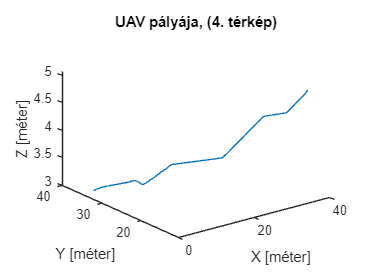

plot3(states(1:(idx-1)*(tStep/hStep+1),2),states(1:(idx-1)*(tStep/hStep+1),1),-states(1:(idx-1)*(tStep/hStep+1),3))
title("UAV pályája, (" + Map +". térkép)")
xlabel("X [méter]")
ylabel("Y [méter]")
zlabel("Z [méter]")


DataMatrixVFH = [states(1:(idx-1)*(tStep/hStep+1),1) states(1:(idx-1)*(tStep/hStep+1),2) -states(1:(idx-1)*(tStep/hStep+1),3)]

DataMatrixVFH =    35.0000    3.0000    3.0000
   35.0000    3.0000    3.0001
   34.9999    3.0001    3.0006
   34.9996    3.0003    3.0013
   34.9990    3.0008    3.0023
   34.9980    3.0015    3.0033
   34.9966    3.0024    3.0044
   34.9946    3.0036    3.0055
   34.9920    3.0051    3.0066
   34.9890    3.0067    3.0077


save("3D\RLVFH\VFHMatrix" + Map +".mat", "DataMatrixVFH")